%MPC Parameters


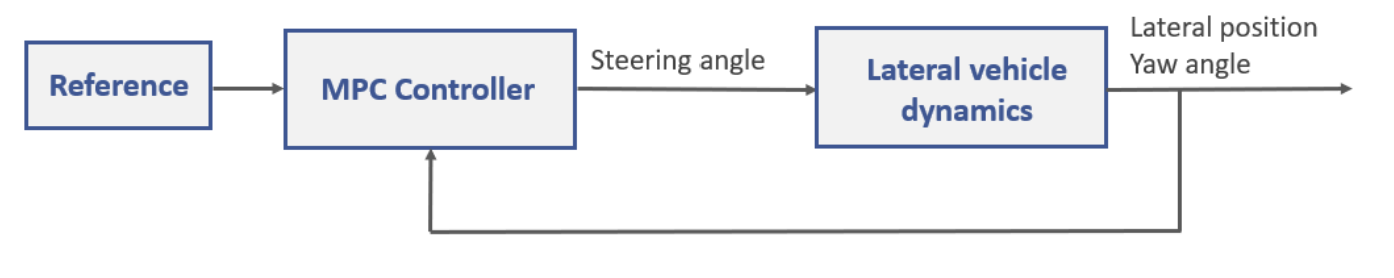


m = 1000;   % Total vehicle mass (kg)
Iz = 2800;  % Yaw moment of inertia of the vehicle (mNs^2)
lf = 1;   % Longitudinal distance from the center of gravity to the front tires (m)
lr = 1.5;   % Longitudinal distance from center of gravity to the rear tires (m)
Cf = 19000; % Cornering stiffness of the front tires (N/rad)
Cr = 33000; % Cornering stiffness of the rear tires (N/rad)
vx = 10;   % Logintudinal Velocity (m/s) 

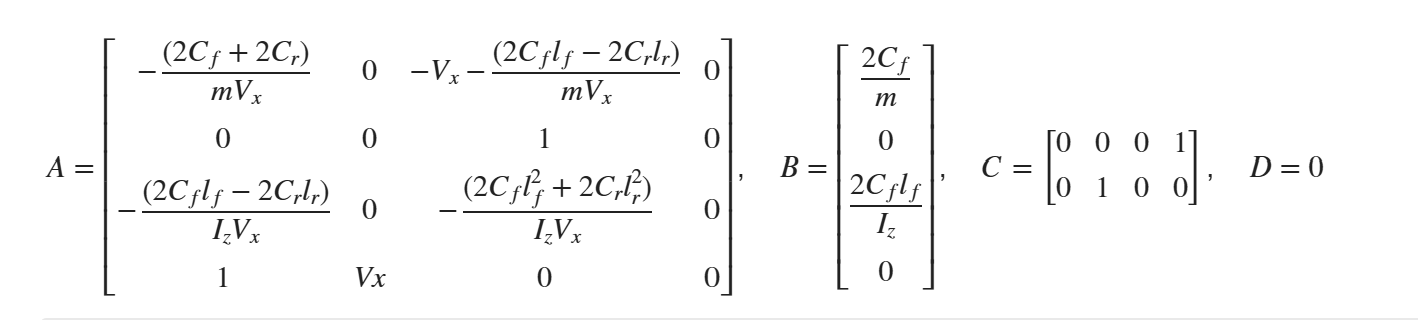

% parameters assumed defined: Cf, Cr, lf, lr, m, Iz, vx

A = [ -((2*Cf)+(2*Cr))/(m*vx),                0,  -vx - ((2*Cf*lf - 2*Cr*lr)/(m*vx)),  0;
       0,                                      0,   1,                                  0;
      -((2*Cf*lf - 2*Cr*lr)/(Iz*vx)),          0, -((2*Cf*lf^2 + 2*Cr*lr^2)/(Iz*vx)),  0;
       1,                                     vx,   0,                                  0 ];

B = [ (2*Cf)/m;
       0;
      (2*Cf*lf)/Iz;   % <-- include lf
       0 ];

% Outputs: [lateral position; yaw angle]
C = [0 0 0 1;
     0 1 0 0];

D = zeros(2,1);

Vehicle = ss(A,B,C,D);

t1= 10;% simulation time of open loop simulation(Plant Characterization)